# Revisiting Fourier and R-C filters

Rasnow 1 Dec 24

We saw the R-C series circuit responded to a sine wave by the voltages Vr and Vc changing amplitude AND phase as a function of frequency. Specifically for example, Vr and Vc were always 90 degrees apart, and +-45 degrees from the source phase and equal amplitude at the corner frequency, $f_c = \frac{1}{2\pi RC$. 

Now I want to explore what happens when the excitation to an R-C series circuit is a square wave. Are the output voltages also square waves with amplitudes and phases that vary with frequency? The answer is a resounding NO. Vr and Vc have "distorted waveforms" much differnet than square waves. With suitable voltage dividers and bias networks, we could measure such waveforms from our function generator's square wave output. That could be a good exercise.

## Spectrum of a square wave

Let's simulate the results here. We can easily simulate a square wave in the time domain, e.g., if we assume a sample rate similar to Arduino's of 10kHz, and the square wave has a frequency of e.g., 200 Hz, then the duration of one period should be (10000 samples/sec)/(200 periods/sec) = 50 samples per period. So we can simulate a square wave in the time domain as:

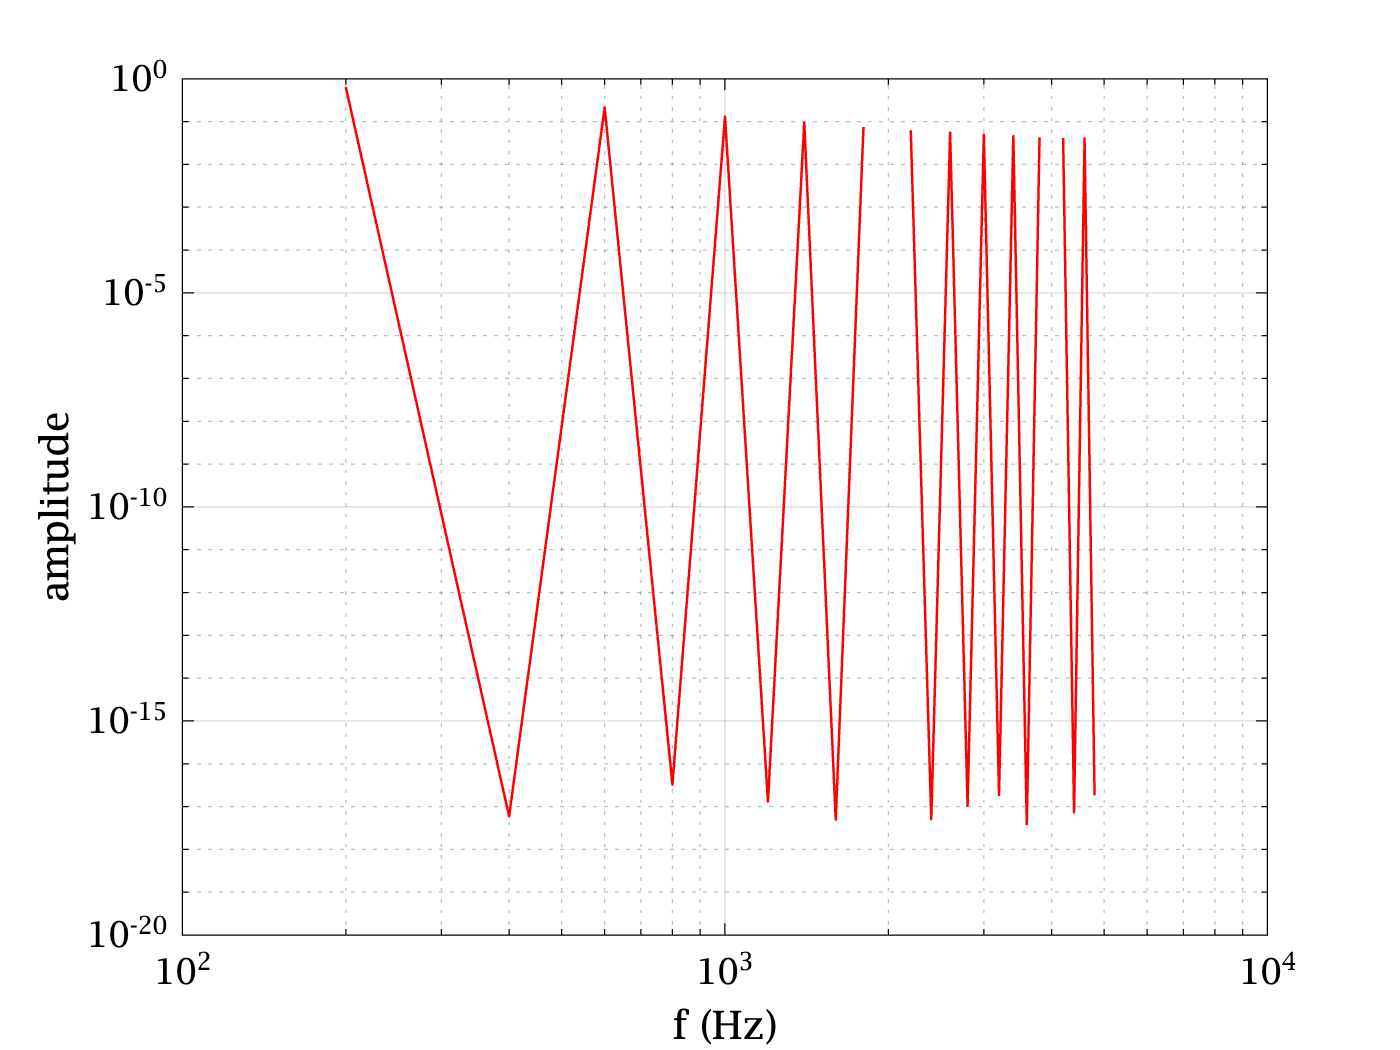

sqWave = [ones(25,1); zeros(25,1)]; % 1 period
[ampl, freq] = aspectrum(sqWave, 1e4);

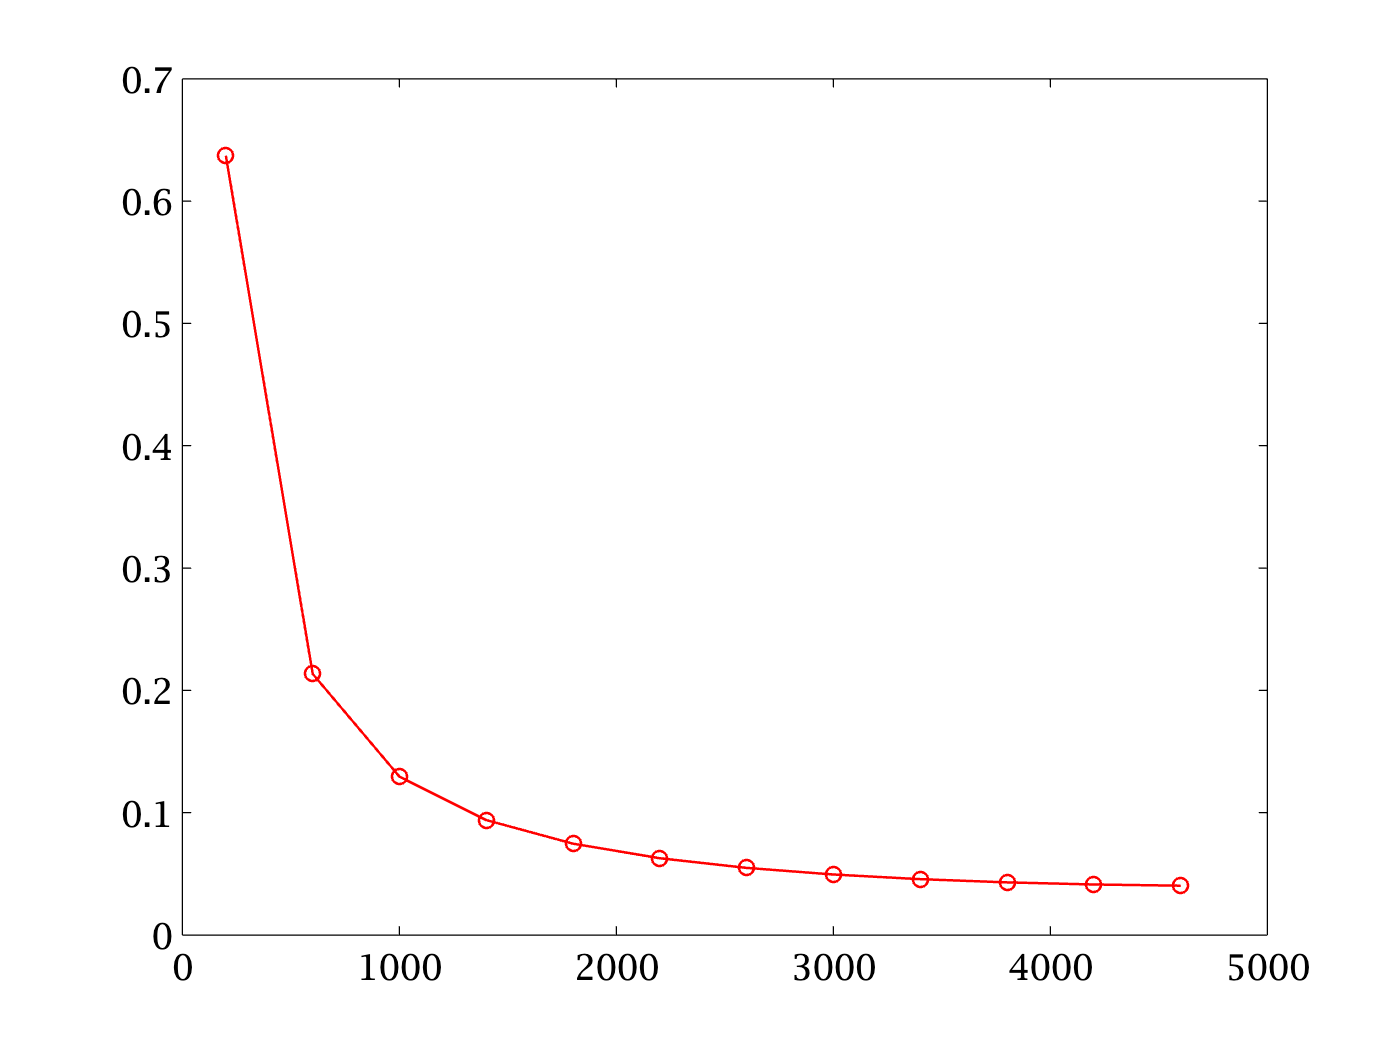

plot(freq(1:2:end),ampl(1:2:end),'o-')

The amplitudes oscillate between around 1 and 1e-16, the noise level for floating point numbers in Matlab. The second plot is just the odd bigger values, on a linear vertical scale. What does theory predict?

The Fourier transform (from the Wikipedia is): 

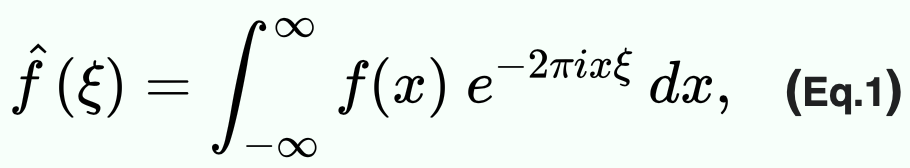

A couple steps are necessary to solve this. First, imagine extending the square wave  periodically to + and - infinity. I won't try to solve this formally (you can look it up in PDE or Fourier Transform texts), but by wave of hand, for frequencies, $\xi$ that aren't integer multiples of the square wave, the phase between $f(x)$ and $e^{-2\pi ix\xi}$ will shift so that somewhere they'll be in phase and somewhere else they'll be out of phase and integrated over the entire domain everything will cancel. Unless the two are phase locked, i.e., $\xi = n/T$ where $T$ is the period of $f(x)$. 

Second, I'm going to skip a bunch of steps and motivation and shortcut to the answer -- again, lots of texts have the missing steps. The sqWave is an odd function as constructed, so we can simplify the integral to a real integral: 


$$\frac{1}{\pi}\int_0^{2\pi}{f(x)sin(nx)dx = \frac{1}{\pi}\int_0^{\pi}{sin(nx)dx = \frac{1}{n\pi}[-cos(n\pi)-1] = \frac{2}{n\pi}$ for $n = $ odd.$$


Let's compare: 

ampl(1:2:floor(end/2))'

ans =     0.6370    0.2135    0.1294    0.0939    0.0747    0.0628


2/pi ./ (1:2:12)

ans =     0.6366    0.2122    0.1273    0.0909    0.0707    0.0579


Close. So a square wave of frequency $f_0$ can be decomposed as  = $\[
\sum_{n=odd}^\infty \frac{2}{n\pi}\sin(n\pi f_0 t)
\]$

## Partial sums

Let's look at partial sums by computing the first n = 1:5 nonzero terms for few hundred different times: 

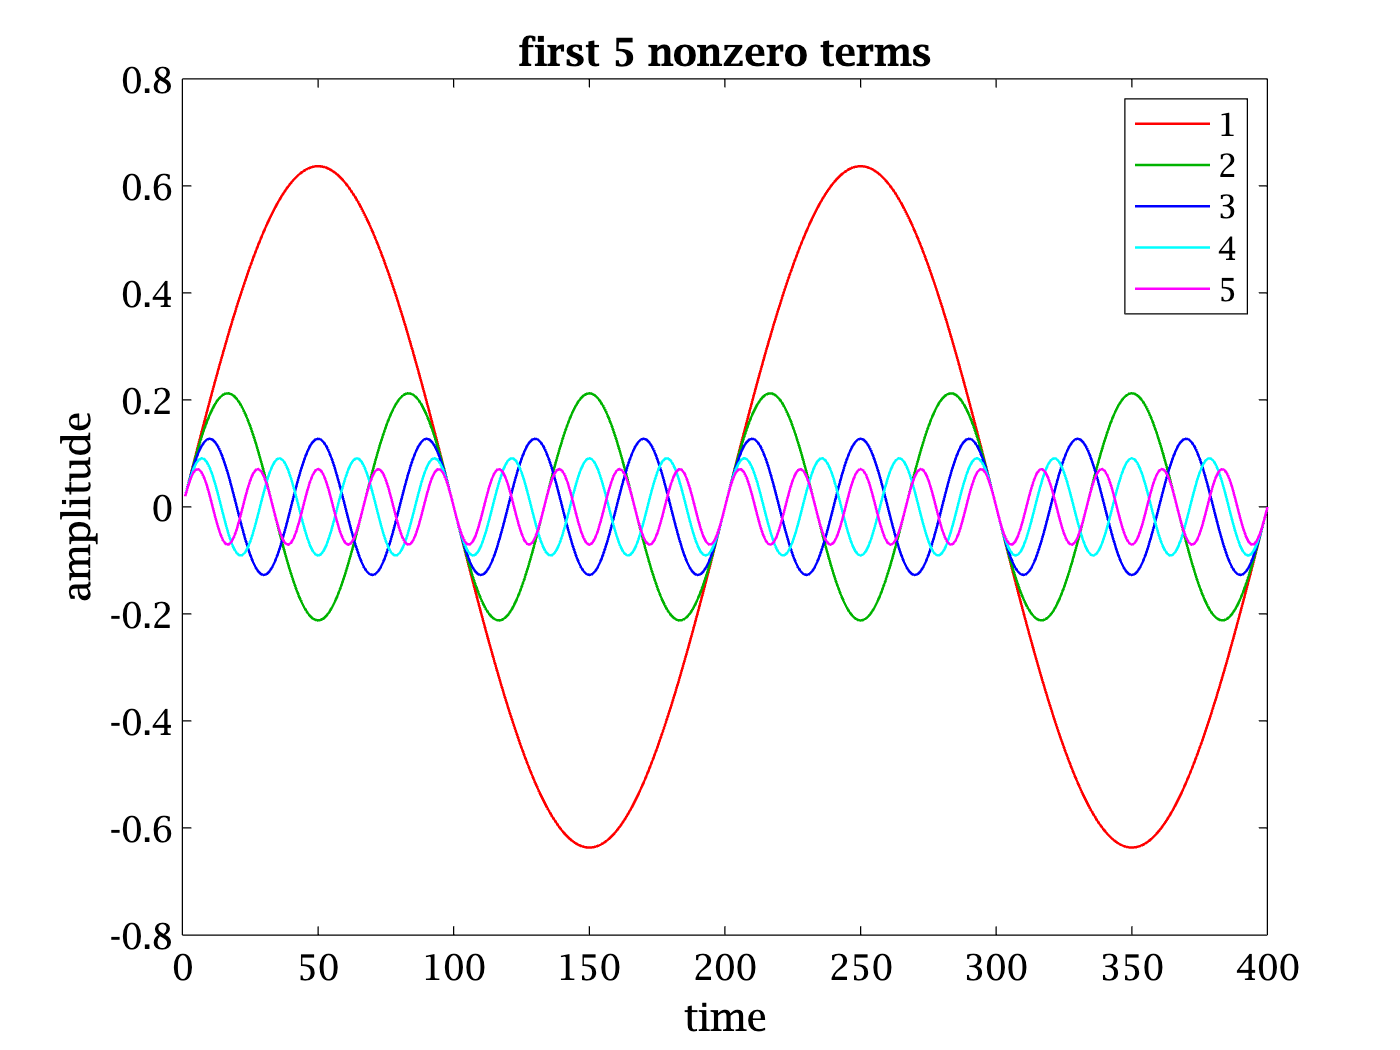

fot = (.01:.01:4)'; % 2 periods = 4*pi radians 
an = zeros(length(fot),5);
for n=1:5
    an(:,n) = 2 / (2*n-1) / pi * sin((2*n-1) * pi * fot); 
end
plot(an); 
xlabel('time'); ylabel('amplitude'); 
title('first 5 nonzero terms'); legend(string(1:5))

You see how the harmonics are all in phase at 0:100:400 samples, or every pi radians. Thus at those phases they add up to fill in the "corners" of the sine wave to make it square. And at the fundamental peaks, the even harmonics are of opposite phase and reduce the peak amplitude (while the odd harmonics are in phase). Let's look at partial sums. We have to do some transposes for `cumsum` (see `>> help cumsum`): 

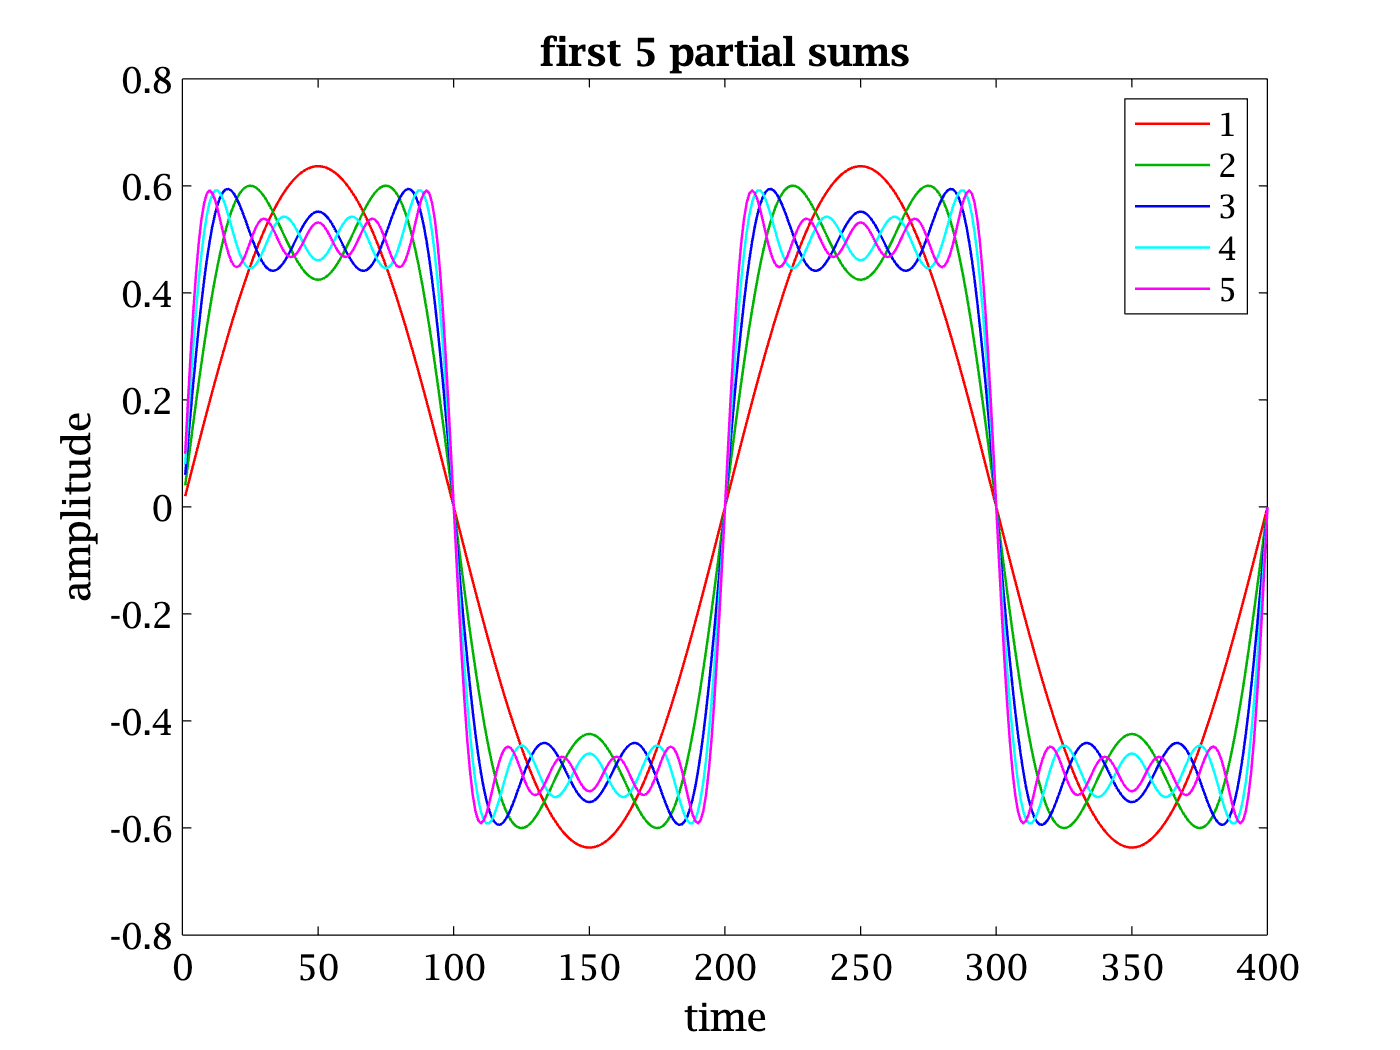

plot(cumsum(an')'); 
xlabel('time'); ylabel('amplitude'); 
title('first 5 partial sums');
legend(string(1:5))

The corners are filling in, and in fact an overshoot is appearing, this is called "[Gibbs phenomena](https://en.wikipedia.org/wiki/Gibbs_phenomenon)". And the top is getting flatter. As an exercise, I encourage you to explore adding in more terms -- like 10, 100, and 1000, to get a feeling for convergence. Then imagine Fourier doing something like this in 1822 -- presumably with candlelight, slide rule (invented 1620-30), ... no Matlab yet;-(. 

## RC circuit simulation

What is the implication of all this? If we run a square wave through an RC circuit, then each frequency will be divided by a different amount, and also phase shifted by a different amount. The voltage over the resistor is $V_R = \frac{V_0R}{R+Z_C}$. But $\[V_0=
\sum_{n=odd}^\infty \frac{2}{n\pi}\sin(n\pi f_0 t)
\]$ and $Z_C=1/(2n \pi f_oC)$ so we get different values for each harmonic $n$. Easiest way to predict how this will all turn out is to simulate it. Applying the square wave we started this activity with to an RC circuit: 

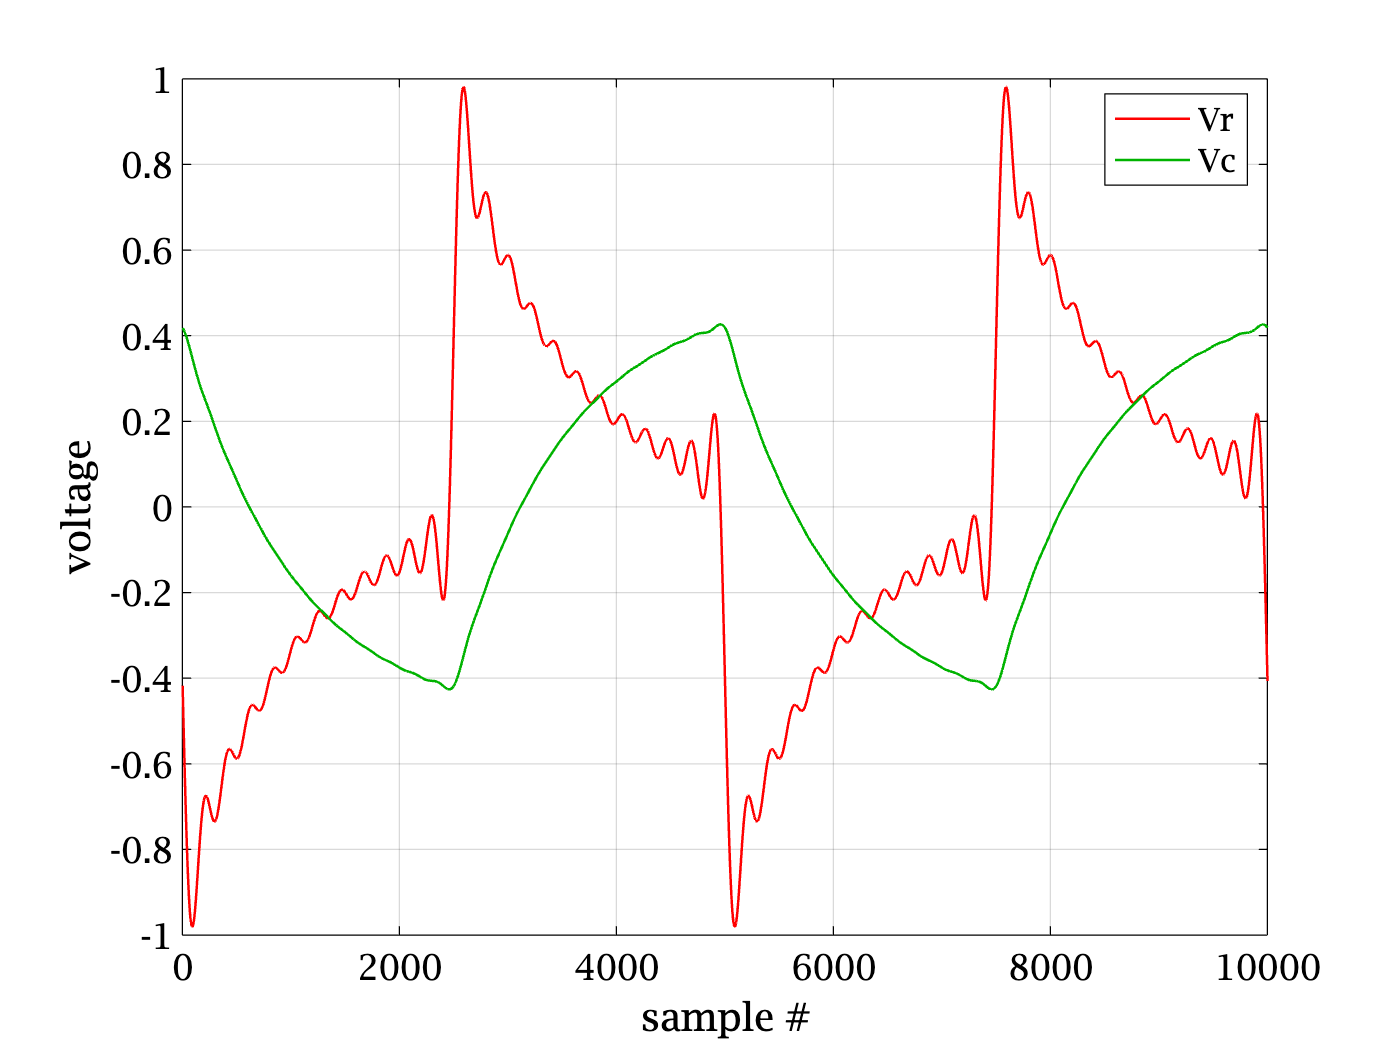

R = 1e4; % ohms
C = .1e-6; % farads
Zc = zc(C,freq);
Vo = ampl*1j; % ampl was absolute valued, so multiply by j for sin 
Vr = Vo .* R ./ (R+Zc); % voltage divider
Vc = Vo .* Zc ./ (R+Zc); % voltage divider
plot(f2t([Vr Vc],2,1e4)); % take complex Vr and Vc back into the time domain
legend('Vr','Vc','location','best');
xlabel('sample #'); ylabel('voltage');
grid

The frequency dependent impedance resulted in a gross *distortion* of the input square wave. The square wave transitions contain lots of high frequency energy, so Zc is small there and the current (and Vr = iR) peak. But as the capacitor charges up to the plateau, current drops along with Vr. The wiggles are called "Gibbs phenomena", [https://en.wikipedia.org/wiki/Gibbs_phenomenon](https://en.wikipedia.org/wiki/Gibbs_phenomenon).   

Recall when I told you sines and cosines (complex exponentials) are "eigenfunctions of linear operators"? Sines and cosines are the only waveforms that don't distort like this square wave, but maintain their shape (except for amplitude and phase shifts, i.e., multiplication by a complex eigenvalue). That is why the frequency domain is so useful. The complex exponentials each obey the voltage divider rules above, but linear combinations of them, e.g., a square wave, aren't eigenvalues, and don't transform through the circuit with just a phase and amplitude shift. Instead these non-eigenfunction waveforms change in much more complex ways, difficult to predict except through Fourier analysis in the frequency domain.

The square wave isn't unique -- see if you can model a triangle wave through an RC filter, and then measure it with your function generator (moving the sine/triangle jumper). 

## Concluding remarks

Roger Penrose, one of the smartest living mathematicians has this diagram in the first chapter of his enormous book, "[Road to Reality](https://www.amazon.com/Road-Reality-Complete-Guide-Universe/dp/0679776311)": 

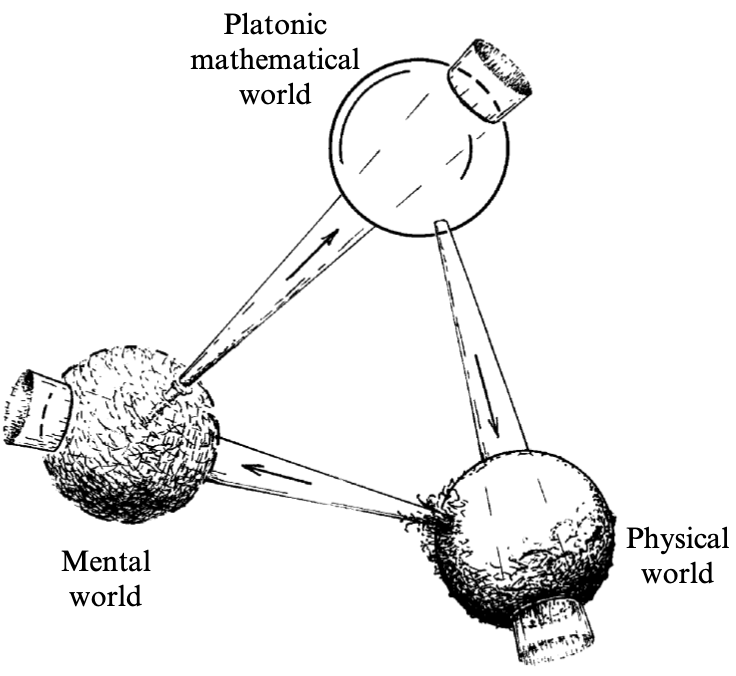

He abstractly represents 3 "worlds" or domains that are "mysteriously" connected: the physical world being the shared reality we live in, with e,g, resistors and capacitors; the Platonic mathematical world which contains mathematical ideas, like Euclid's idealized points and lines, along with Fourier transforms, algebra, etc.; and the world inside our heads consisting of all the things we might imagine and understand. A subset of our mental world consists of or relate to a subset of the mathematical world. A subset of the mathematical universe has an uncanny similarity to a subset of the physical world. And we can internalize, model, and understand (at some level) a subset of the physical world. What we've explored here instantiates some of these diverse connections and domains. Imagine (or better yet, actually build in the physical world) an RC filter connected to a square wave voltage and measure Vr and Vc. The voltage waveforms on the physical resistors and capacitors are what they are in the physical world -- no amount of imagination or desires (or changing the channel to Fox News) will change them. They're just doing what they do according to the laws of E&M and physics. Then there are the mathematical models we've created -- inhabitants of the Platonic mathematical world, built with voltage divider equations, complex `zc.m`, `f2t.m`, etc., following the rules of mathematics (instantiated with Matlab). And both of these seemingly radically different systems produce the same results, the same waveforms!! Why?? What does that tell us?? There are many deep (and not so deep) philosophical lessons, but let's focus on practical ones now. The mathematics we've used here is a good model of the physical phenomena. It exhibits enough complexity to replicate the complicated waveforms of these ciruits. Nobody has found simpler mathematical models that are as accurate, so we should feel lucky to have what we have: 3 parallel universes where we can explore electronic phenomena. Discoveries can be made in any of these worlds, but they shouldn't be believed until verified in at least another world. The more facile we are at moving between these worlds, the better we can validate and calibrate our understanding so it mirrors reality and gives us more power to manipulate and model these worlds. 